## Assignment 2

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

### Task 1:

%% Constants
mu = 398600.4418;            % km^3/s^2, 
Re   = 6378.1363;            % [km]
J2   = 1.08262668e-3;        % [-]

%% Table 
r1 = [3419.8556; 6019.8260; 2784.6002];   % km
r3 = [2434.9520; 6597.3867; 2521.5231];   % km
t1 = 0.0;                     % s
t3 = 2*60 + 33.04;            % s
dt13 = t3 - t1;               % time of flight

% Class instances
OP = OrbitPropagation;
OD = OrbitDetermination;


## 1a) Gauss-Lambert: calculate v1 and v2

% -> Computes the initial and final velocity vectors that connect r1 and r3
[v1, v3] = OD.solve_lamperts_problem_gauss(r1, r3, t1, t3, mu);


## 1b) Convert obtained Cartesian states to Keplerian elements

[a1, e1, i1, RAAN1, omega1, nu1] = OP.convert_car2kep(r1, v1, mu);
[a3, e3, i3, RAAN3, omega3, nu3] = OP.convert_car2kep(r3, v3, mu);

% Display keplarian elments
% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a1, e1, i1, RAAN1, omega1, nu1

a1 = 8.2913e+03

e1 = 0.1000

i1 = 0.4363

RAAN1 = 5.2360

omega1 = 2.0595

nu1 = 2.3473e-05

a3, e3, i3, RAAN3, omega3, nu3

a3 = 8.2913e+03

e3 = 0.1000

i3 = 0.4363

RAAN3 = 5.2360

omega3 = 2.0595

nu3 = 0.1571

Running task 1 delivers the same Keplerian elements based on the 2 measurements. The orbit is an almost circular orbit (e ~ 0) with an inclination of 25° and approximate orbital height of around 1900 km (LEO). A graphical representation of the orbit can be seen below.

## 1c) Propagate one full orbit using RK4 (including J2 perturbation)

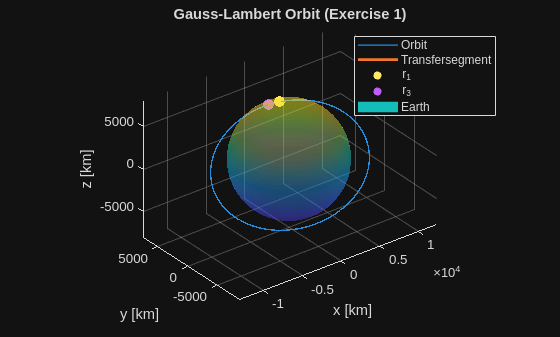

T = 2*pi * sqrt(a1^3 / mu);   % Orbital period [s]

dtStep = T / 500;             % time step [s]
% Full orbit propagation
[tOrb, rOrb, vOrb] = OP.propagate_orbit_EoM_rk4(r1, v1, 0, T, dtStep, mu, Re, J2);

% Propagate only the transfer segment between r1 and r2
[tSeg, rSeg, vSeg] = OP.propagate_orbit_EoM_rk4(r1, v1, t1, t3, dtStep, mu, Re, J2);

%% Plot: Orbit, transfer segment and vectors
figure; hold on; grid on; axis equal;

% Full orbit
plot3(rOrb(:,1), rOrb(:,2), rOrb(:,3), 'LineWidth', 1);

% Transfersegment
plot3(rSeg(:,1), rSeg(:,2), rSeg(:,3), 'LineWidth', 2);

% Vector points r1 and r3
scatter3(r1(1), r1(2), r1(3), 60, 'filled');
scatter3(r3(1), r3(2), r3(3), 60, 'filled');

% Earth
[xe, ye, ze] = sphere(40);
surf(Re*xe, Re*ye, Re*ze, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
legend('Orbit', 'Transfersegment', 'r_1', 'r_3', 'Earth');
title('Gauss-Lambert Orbit (Exercise 1)');
view(3);

### Task 2 – Gibbs Method for Orbit Determination:

%Given position vectors from tables
r1 = [0; 0; 6378.137];   % km
r2 = [0; -4464.696; -5102.509];   % km
r3 = [0; 5740.323; 3189.068];   % km


## 2a) Compute v2 using Gibbs method (3 position vectors): solve for v_2 [km/s]

[v1, v2, v3] = OD.solve_gibbs_method(r1, r2, r3, mu);
v2

v2 =          0
    5.5311
   -5.1918


The resulting velocity matches the given verification value in task 2 with a small deviation  of 2,578e-07  km / s.

% % Compare with provided verification vector and calculate norm
v2_test = [0; 5.531148; -5.191806];  % km/s
diff  = norm(v2 - v2_test)

diff = 2.5782e-07

## 2b) Convert to Kepler elements (orbit from r2 and v2)

[a2, e2, i2, RAAN2, omega2, nu2] = OP.convert_car2kep(r2, v2, mu);

% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]

The resulting measurement results in a VLEO orbit, with a nearly circular orbit. with a high inclination of about 86° and an orbital height of 261 km. 

a2, e2, i2, RAAN2, omega2, nu2

a2 = 6.6398e+03

e2 = 0.0408

i2 = 1.5708

RAAN2 = 1.5708

omega2 = 1.8442

nu2 = 2.1494

### Task 3 - Herrick–Gibbs Method:

% Given measurements (3 position vectors + time stamps)
r1 = [3419.8556; 6019.8260; 2784.6002];   % km
r2 = [2935.9119; 6326.1832; 2660.5958];   % km
r3 = [2434.9520; 6597.3867; 2521.5231];   % km

t1 = 0.0;                            % 0.0 s
t2 = 1*60 + 16.48;                   % 1 min 16.48 s = 76.48 s
t3 = 2*60 + 33.04;                   % 2 min 33.04 s = 153.04 s


## 3a) Compute v2 using Herrick–Gibbs

v2_HG = OD.solve_gibbs_herrik_method(r1, r2, r3, [t1; t2; t3], mu)

v2_HG =    -6.4416
    3.7776
   -1.7206


The resulting velocity matches the given verification value in task 3 with a small deviation  of 8,9657e-05  km / s.

% Compare with given and calculate norm
v2_test = [-6.4416; 3.7776; -1.7205];   % km/s 
diff = norm(v2_HG - v2_test)

diff = 8.9657e-05

## 3b) Convert to Kepler elements from r2 and v2_HG

[a2, e2, i2, RAAN2, omega2, nu2] = OP.convert_car2kep(r2, v2_HG, mu);

% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a2, e2, i2, RAAN2, omega2, nu2

a2 = 8.2913e+03

e2 = 0.1000

i2 = 0.4363

RAAN2 = 5.2360

omega2 = 2.0595

nu2 = 0.0785

The resulting orbit is an almost circular orbit with a low eccentricity and an orbital height of around 1913,2 km, and a inclincation of 24 degrees which is similar to the results in task 1.

### Task 4 – Angles-Only Orbit Determination (Extended Gauss):

% Load observation dataset (RA/DEC + ground station)
load("observations.mat");
idx = [62, 70, 74];
llalla = Sat11Access(idx, ["lat","long", "h_km_"]).Variables;

% build UTC datetime from table columns
trows = Sat11Access(idx, ["year","month","day","h","min","sec"]).Variables;

% create R_GS from lla and convert altitude to meters
temp = llalla;
temp(:,3) = temp(:,3) * 1000;
R_GS = lla2eci(temp, trows)';
R_GS = R_GS / 1000;

% Extract numeric values for each row
vals1 = Sat11Access{62, ["delta", "alpha"]};
vals2 = Sat11Access{70, ["delta", "alpha"]};
vals3 = Sat11Access{74, ["delta", "alpha"]};

L_i = @(delta, alpha) [cos(delta) * cos(alpha); cos(delta) * sin(alpha); sin(delta)];

% Call the function
L_62 = L_i(deg2rad(vals1(1)), deg2rad(vals1(2)));
L_70 = L_i(deg2rad(vals2(1)), deg2rad(vals2(2)));
L_74 = L_i(deg2rad(vals3(1)), deg2rad(vals3(2)));

LOS = [L_62, L_70, L_74];

## Solve angles-only orbit determination (Extended Gauss)

[R_ecef, vv_2_ecef] = OD.solve_angles_only_approach_extended(LOS, R_GS, posixtime(datetime(trows)), mu, 1E-9, 100);

Error using OrbitDetermination/solve_angles_only_approach_extended (line 330)
No method could be applied to solve for v_2

[rr_2_eci, vv_2_eci] = ecef2eci(trows(2,:), R_ecef(:,2), vv_2_ecef);


## 4b) Kepler elements from r2 and v2_HG

[a2, e2, i2, RAAN2, omega2, nu2] = OP.convert_car2kep(rr_2_eci, vv_2_eci, mu);

% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a2, e2, i2, RAAN2, omega2, nu2

## 4c) Sensitivity Study: Run 10 Random Angles-Only Triplets

N_sets = 10;                      
N_obs  = height(Sat11Access);

a_list     = zeros(N_sets,1);
e_list     = zeros(N_sets,1);
i_list     = zeros(N_sets,1);
RAAN_list  = zeros(N_sets,1);
omega_list = zeros(N_sets,1);
nu_list    = zeros(N_sets,1);

kSet = 1;


while kSet <= N_sets
    
    % Create random triplets with appropiate spacing between observations
    idx1 = randperm(N_obs - 10, 1);
    idx = idx1 + [1, 5, 9];

    % extract lat/long
    llalla = Sat11Access(idx,["lat","long", "h_km_"]).Variables;
    temp = llalla;
    temp(:,3) = temp(:,3) * 1000;
    R_GS = lla2ecef(temp)';
    R_GS = R_GS / 1000;
    
    % build UTC datetime from table columns
    trows = Sat11Access(idx, ["year","month","day","h","min","sec"]).Variables;
        
    % Extract numeric values for each row
    vals1 = Sat11Access{idx(1), ["delta", "alpha"]};
    vals2 = Sat11Access{idx(2), ["delta", "alpha"]};
    vals3 = Sat11Access{idx(3), ["delta", "alpha"]};
        
    L_i = @(delta, alpha) [cos(delta) * cos(alpha); cos(delta) * sin(alpha); sin(delta)];
    
    % Call the function
    L_1 = L_i(deg2rad(vals1(1)), deg2rad(vals1(2)));
    L_2 = L_i(deg2rad(vals2(1)), deg2rad(vals2(2)));
    L_3 = L_i(deg2rad(vals3(1)), deg2rad(vals3(2)));
    
    LOS = [L_1, L_2, L_3];
    
    % If gab between epochs is to big, try another triplet
    try 
        [R, vv_2] = OD.solve_angles_only_approach_extended(LOS, R_GS, posixtime(datetime(trows)), mu, 1E-9, 100);
    catch

    end
    rr_2 = R(:,2);
    rr_2 = ecef2eci(trows(2,:), rr_2, vv_2);
    [a, e, i, RAAN, omega, nu] = OP.convert_car2kep(rr_2, vv_2, mu);

    a_list(kSet) = a;
    e_list(kSet) = e;
    i_list(kSet) = i;
    RAAN_list(kSet) = RAAN;
    omega_list(kSet) = omega;
    nu_list(kSet) = nu;

    kSet = kSet + 1;

end

%% Compare the change of sami major axis and eccentricity

figure;
subplot(2,1,1);
plot(1:N_sets, a_list, 'o-'); grid on;
xlabel('Set Number'); ylabel('a [km]');
title('Variation of a over observationstriplets');

subplot(2,1,2);
plot(1:N_sets, e_list, 'o-'); grid on;
xlabel('Set Number'); ylabel('e [-]');
title('Variation of e over observationstriplets');